syms y(x)
eqn = diff(y,x) == exp(-x^2)*y^2;
% 1
cond = y(0)==0;
ySol(x) = dsolve(eqn,cond);
ySol(x)

$$ans = 0$$

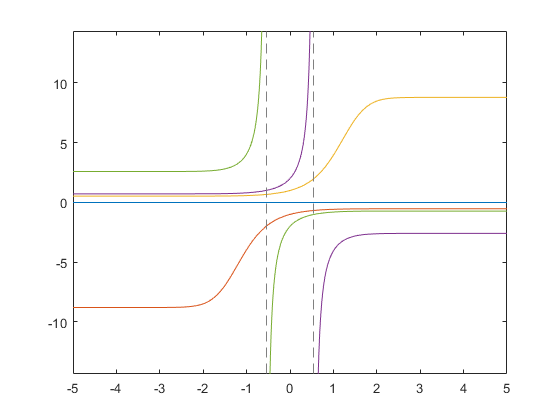

fplot(ySol(x));
hold on
% 2
cond = y(0)==-1;
ySol(x) = dsolve(eqn,cond);
fplot(ySol(x));
% 3
cond = y(0)==1;
ySol(x) = dsolve(eqn,cond);
fplot(ySol(x));
% 4 
cond = y(0)==2;
ySol(x) = dsolve(eqn,cond);
fplot(ySol(x));
% 5 
cond = y(0)==-2;
ySol(x) = dsolve(eqn,cond);
fplot(ySol(x));
hold off

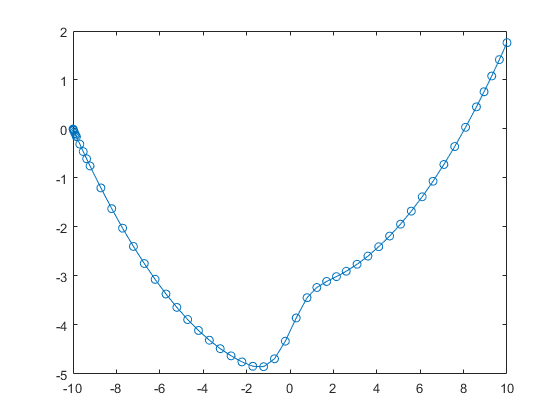


% Numerical
tspan = [-10 10];
y0 = 0;
[x,y] = ode45(@(x,y) exp(-x^2)+0.1*x, tspan, y0);
plot(x,y,'-o')